% Rollercoaster Simulation 
% Chris Allum - April 8th 2021
clc
clearvars


% run simulation
B = 0.5;
[t,p] = simulation(B);

% plotting
x = p(:,1);
y = p(:,3);

figure
plot(x,y)
title("Position of Cart B = 0.5")
xlabel("X Position (m)")
ylabel("Y Position (m)")

ride_length = t(end)

ride_length = 27.0679

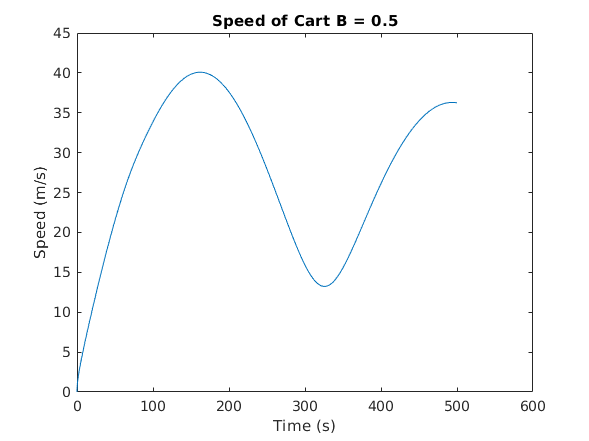


figure
speed = sqrt(p(:,2).^2 + p(:,4).^2);
plot(x, speed)
title("Speed of Cart B = 0.5")
xlabel("Time (s)")
ylabel("Speed (m/s)")

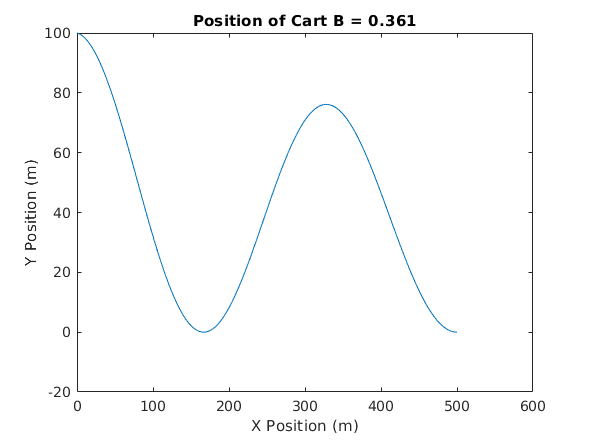

% run 2nd simulation
B = 0.361;
[t,p] = simulation(B);

% plotting
x = p(:,1);
y = p(:,3);

figure
plot(x,y)
title("Position of Cart B = 0.361")
xlabel("X Position (m)")
ylabel("Y Position (m)")


ride_length = t(end)

ride_length = 42.3930

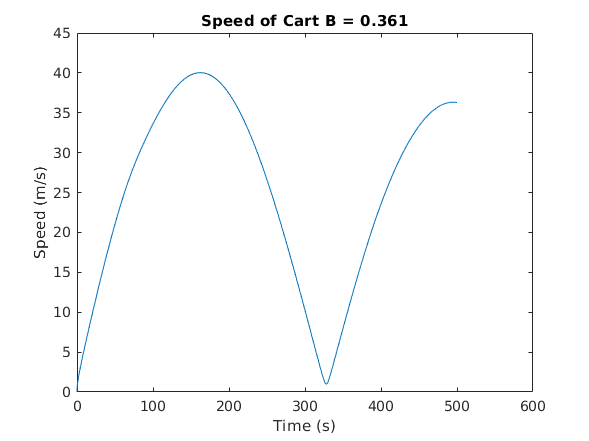


figure
speed = sqrt(p(:,2).^2 + p(:,4).^2);
plot(x, speed)
title("Speed of Cart B = 0.361")
xlabel("Time (s)")
ylabel("Speed (m/s)")

function [t,p] = simulation(B)

    % time span
    tspan = [0:.05:50];
    
    % simulation params, used in ODE funcs
    x = sym('x');
    
    L = 500;
    h = 100;
    %B = .5;
    
    y = @(x) h*(1-B*x/L)*cos(3*pi*x/(2*L))^2;
    
    a = matlabFunction(diff(y(x)));

    b = matlabFunction(diff(a(x)));
    
    g = 9.8;    % m/s^2
    A = 4;      % m^2
    Cd = 0.1;   % ???
    rho = 1.02; % kg/m^3
    m = 500;    % kg
    
    c = rho*Cd*A/(2*m);
    
    % initial position
    x0 = 0;
    y0 = 100;
    
    % initial velocity
    dx = 0;
    dy = 0;

    % pack initial conditions into column vector
    init = [x0 dx y0 dy]';
    
    % use ode45 and stop at event
    options = odeset('Events', @eventFcn,"RelTol",1.0e-6);
    [t,p] = ode45(@f,tspan,init,options);
    
    % define ODEs
    function dpdt = f(~,p)
        
        V = norm([p(2) p(4)]);
        
        Q = [1 0 0 0 0;
             0 1 0 0 0;
             0 0 1 0 a(p(1))/(m*sqrt(1+a(p(1))^2));
             0 0 0 1 -1/(m*sqrt(1+a(p(1))^2));
             0 0 a(p(1)) -1 0];
        
        r = [p(2) p(4) -c*V^2/(sqrt(1+a(p(1)))) -c*a(p(1))*V^2/(sqrt(1+a(p(1))))-g -b(p(1))*p(2)^2]';
        
        
        z = (Q\r)';
        
        dx = z(1);
        dy = z(2);
        ddx = z(3);
        ddy = z(4);
        
        dpdt = [dx ddx dy ddy]';
    end
    
    function [position,isterminal,direction] = eventFcn(~,p)
        position = p(1)-L; % The value that we want to be zero
        isterminal = 1;  % Halt integration 
        direction = 1;   % The zero can be approached from either direction
    end

end
